# Bike Frequency

i krysset mellom Elgeseter bru og Studentersamfundet

Observert fra en kafé med utsikt mot mesteparten av krysset, bortsett fra svingen i motsatt retning av Samfundet

## Initialization and Display of Raw Data

Reading from `freqs.csv` into time and bike arrays

A = textscan(fopen("freqs.csv"), '%s %d', 'Delimiter',',');
time = A{1};
bikes = A{2};
if size(bikes) ~= size(time)
    disp('oh snap, invalid sizes')
end

Finding total and accumulating count of bikes

total = sum(bikes);
disp(strcat('In total, ', string(total), ...
    ' bikes passed during 30 minutes'))

In total,78 bikes passed during 30 minutes


disp(strcat('That means 𝜆=', string(total / 30), ...
    ' bikes pass on average every minute'))

That means 𝜆=2.6 bikes pass on average every minute


bikes = cumsum(bikes);

Converting strings to `MATLAB` timestamps

time = datetime(time, 'Format','mm:ss');

Plotting a graph

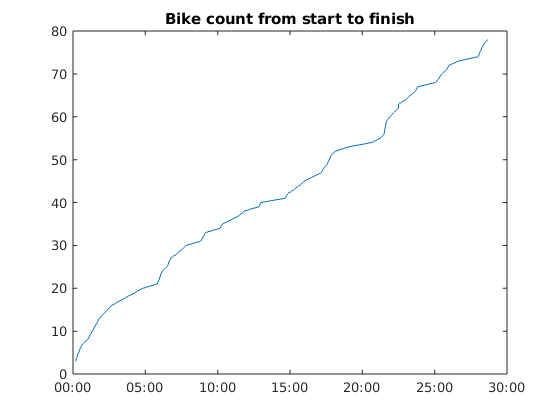

plot(datenum(time), bikes)
title('Bike count from start to finish')
datetick('x', 'MM:SS')

## A: Sentralmål og variasjon - split into counts for each minute

Reading reformatted data, split by 0-indexed minutes

B = textscan(fopen("minutes.csv"), '%d %d', 'Delimiter',',');
minute = B{1};
minute_bikes = B{2};
if sum(minute_bikes) ~= total
    disp('wrong count of bikes divided by minute')
elseif size(minute) ~= size(zeros(30, 1))
    disp('you forgot a minute')
    disp(size(minute))
end

Plotting columns

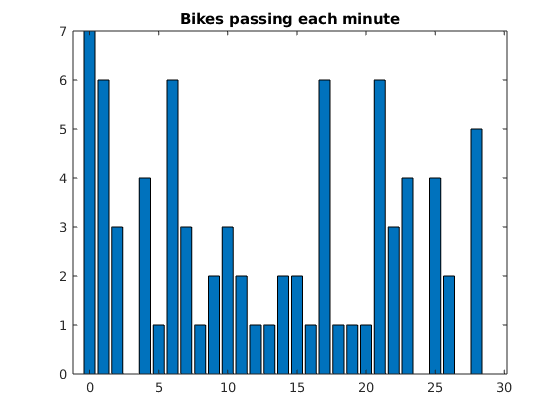

bar(minute, minute_bikes)
title('Bikes passing each minute')

Sentralmål

sprintf('%.2f bikes passed on average', mean(minute_bikes))

ans = '2.60 bikes passed on average'

% sorted_bikes = sort(minute_bikes);
% Not necessary to sort since median() sorts for us
sprintf('Median: %d', median(minute_bikes))

ans = 'Median: 2'

sprintf('Mode (typetall): %d', mode(minute_bikes))

ans = 'Mode (typetall): 1'

Variasjonsbredde og standardavvik

sprintf('Range (variasjonsbredde): %d', range(minute_bikes))

ans = 'Range (variasjonsbredde): 7'

% Also possible: max(minute_bikes) - min(minute_bikes)
sprintf('Standard deviation (standardavvik): %f', std(double(minute_bikes)))

ans = 'Standard deviation (standardavvik): 2.094327'

## B: Poisson Distribution, Estimates

### Calculating Lambda


$$\hat{\lambda} = \frac{x}{t}$$


lambda = total / 30;

### With t = 1 minute

– lower reliability

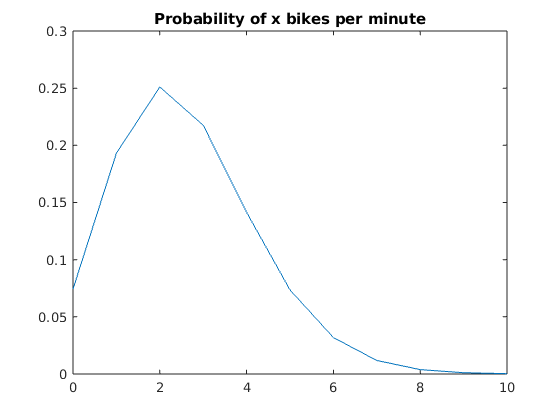

x = 0:10;
plot(x, poisspdf(x,lambda))
title('Probability of x bikes per minute')

### With t = 30 minutes

– which matches the circumstances of our original data


$$\hat{\lambda} \cdot t = \frac{x}{t}\cdot t = x$$


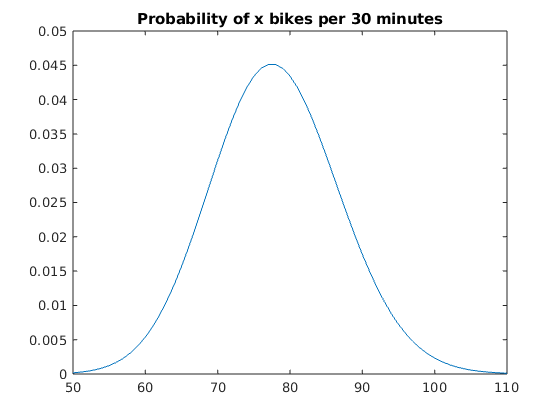

x = 50:110;
plot(x, poisspdf(x,total))
title('Probability of x bikes per 30 minutes')